# Simulaciones Realistas Finales de TFG

 Se comienza concatenando las cuatro grandes partes del itinerario:

- Problema de Lambert Tierra-Marte

- Fly by en torno a Marte

- Problema de Lambert Márte-Júpiter

- Órbita Parking en Júpiter

Además, se ilustra el perfil del módulo y las componentes de la velocidad de la aeronave:

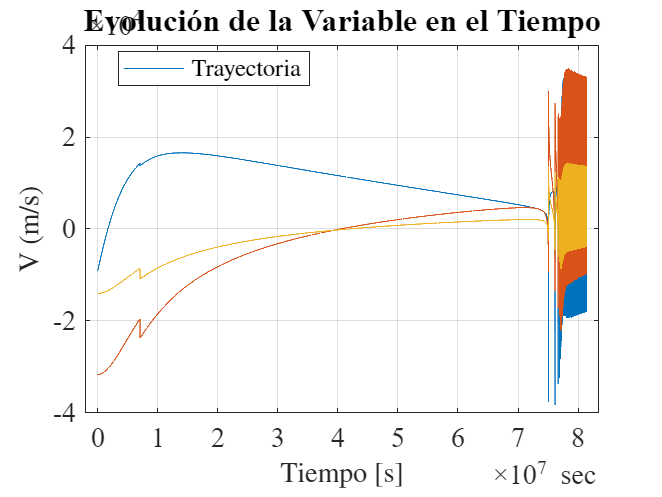

%Se debe emplear el workspace de "Fly_by_ICRF"
clc;clear;close all
load('Datos_control.mat')
%Parámetros orbitales LAMBERT 1
%...Algorithm 4.1 (using r1 and v1):
coe = coe_from_sv(r_earth, v_0,mu_sun);
%...Save the initial true anomaly:
TA0 = coe(6);
sma=coe(7)*1000;
ecc=coe(2);
inc=coe(4)/deg;
RAAN=coe(3)/deg;
aop=coe(5)/deg;
true_an=TA0/deg; %Initial true anomaly

tof=timeIntervals(1);

%Concatenación de las timetables
% Timetable 1 (empieza en 0 sec)
TT2_r = timetable(seconds(t_flyby(1:1507)), r_flyby(1:1507,1:3)*1000, 'VariableNames', {'Data'});
TT2_v= timetable(seconds(t_flyby(1:1507)), dydt_store(1:1507,1:3)*1000, 'VariableNames', {'Data'});

%Ajustes de tiempo
r_satelite_Lambert_1 = r_satelite_Lambert_1(1:1941, :);
v_satelite_Lambert_1 = v_satelite_Lambert_1(1:1941, :);
ultimoTiempo = r_satelite_Lambert_1.Time(end);
primerTiempo=ultimoTiempo;
TT2_r.Time=TT2_r.Time + ultimoTiempo;
TT2_v.Time=TT2_v.Time + ultimoTiempo;
ultimoTiempo=TT2_r.Time(end);
r_satelite_Lambert_2.Time=r_satelite_Lambert_2.Time+ultimoTiempo-r_satelite_Lambert_2.Time(1);
v_satelite_Lambert_2.Time=v_satelite_Lambert_2.Time+ultimoTiempo-v_satelite_Lambert_2.Time(1);%-v_satelite_Lambert_2.Time(1);
%Fusión de las timetable

ultimo_Tiempo=seconds(ultimoTiempo);
R_Trayectoria_completa=[r_satelite_Lambert_1;TT2_r;r_satelite_Lambert_2];
V_Trayectoria_completa=[v_satelite_Lambert_1;TT2_v;v_satelite_Lambert_2];

ultimo_Tiempo=ultimo_Tiempo;
%Vale, ahora tenemos la trayectoria completa. Necesito hacer que el
%programa sea capaz de cambiar el paso de integración cuando yo le diga.
%Además, molaría implementar que la propulsión se activase cuando el
%satélite sobrepasara r_out

tof=seconds(R_Trayectoria_completa.Time(end));

figure
plot(V_Trayectoria_completa.Time, V_Trayectoria_completa{:, 1})
grid on

% Personalizar los ejes
xlabel('Tiempo [s]', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('V (m/s)', 'Interpreter', 'latex', 'FontSize', 14);
title('Evolución de la Variable en el Tiempo', 'Interpreter', 'latex', 'FontSize', 16);

% Añadir la leyenda
legend({'Trayectoria'}, 'Location', 'best', 'Interpreter', 'latex', 'FontSize', 12);

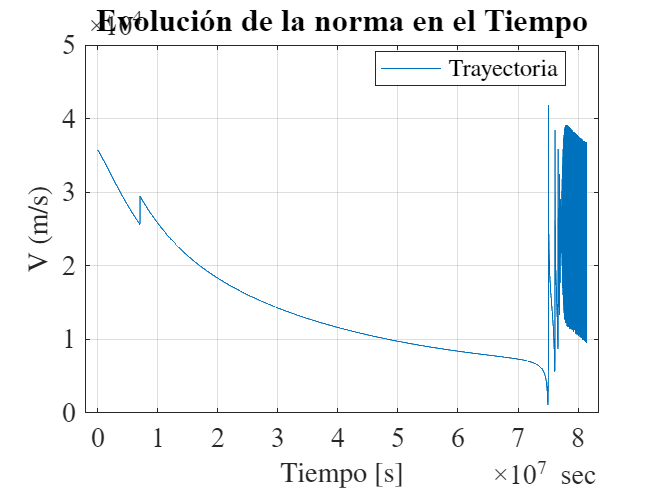


%Plot del módulo 

figure
vel_norm = vecnorm(V_Trayectoria_completa.Data, 2, 2);
plot(V_Trayectoria_completa.Time, vel_norm)
grid on

% Personalizar los ejes
xlabel('Tiempo [s]', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('V (m/s)', 'Interpreter', 'latex', 'FontSize', 14);
title('Evolución de la norma en el Tiempo', 'Interpreter', 'latex', 'FontSize', 16);

% Añadir la leyenda
legend({'Trayectoria'}, 'Location', 'best', 'Interpreter', 'latex', 'FontSize', 12);

A continuación, se calcula la posición de Marte en forma de Timetable, indispensable para que la influencia del planeta sea la misma supuesta en anteriores desarrollos. La interna al propagador orbital de Simulink no funciona bien. Da efemérides distintas.

También se da una tabla con información muy interesante sobre el itinerario. Faltaría incluir los datos de la órbita de parking. Eso esta en el archivo 

%Calculamos las efemérides de Marte para los tiempos de la timetable R_Trayectoria_completa

departure_date=startDate1;
time_points=seconds(R_Trayectoria_completa.Time)/(24*60*60);
julian_points=departure_date+time_points;
[Mars_position]=planetEphemeris(julian_points,'Sun','Mars')*1000;
TT_Mars_r = timetable(R_Trayectoria_completa.Time, Mars_position(:,1:3), 'VariableNames', {'Data'});
v_2=v_2*1000;

%Datos interesantes
fprintf('\n===================================================\n');

fprintf('     INFORME DE MANIOBRA\n');

     INFORME DE MANIOBRA


fprintf('===================================================\n\n');


fprintf('\n Ángulo de Desviación (°) = %g', angulo_desviacion);


 Ángulo de Desviación (°) = 2.09779

fprintf('\n Ángulo de Desviación Total (°) = %g', acos(v_out_sim*(v_2/1000)'/(norm(v_out_sim)*norm(v_2/1000)))*(180/pi));


 Ángulo de Desviación Total (°) = 5.65211

fprintf('\n Diferencia en la Norma (respecto a la teórica) (km/s) = %g', norm(v_out_th)-norm(v_out_sim));


 Diferencia en la Norma (respecto a la teórica) (km/s) = 1.33446

fprintf('\n Diferencia en la Norma Total (respecto a la velocidad v2)(km/s) = %g', norm(v_2/1000)-norm(v_out_sim));


 Diferencia en la Norma Total (respecto a la velocidad v2)(km/s) = 3.59032

fprintf('\n v_out_sim (km/s) = [%g %g %g]',v_out_sim(1), v_out_sim(2), v_out_sim(3))


 v_out_sim (km/s) = [14.1651 -19.7554 -8.73402]

fprintf('\n v_2 (km/s) = [%g %g %g]',v_2(1)/1000, v_2(2)/1000, v_2(3)/1000)


 v_2 (km/s) = [13.651 -23.6898 -10.8637]

fprintf('\n v_2 - v_out_sim (km/s) = [%g %g %g]',(v_2(1)/1000)-v_out_sim(1), (v_2(2)/1000)-v_out_sim(2),(v_2(3)/1000)-v_out_sim(3))


 v_2 - v_out_sim (km/s) = [-0.514126 -3.93447 -2.12964]

fprintf('\n diff_v  (unitario) = [%g %g %g]',diff_v(1), diff_v(2),diff_v(3))


 diff_v  (unitario) = [-0.118115 -0.873544 -0.472197]

fprintf('===================================================\n\n');

tabla_final= T(368, :);

Valores_a_agnadir=[rrpp,angulo_desviacion,acos(v_out_sim*(v_2/1000)'/(norm(v_out_sim)*norm(v_2/1000)))*(180/pi),norm(v_out_th)-norm(v_out_sim),norm(v_2/1000)-norm(v_out_sim)];
nombre_columna = {'Angulo_Desviacion_v_th_deg', ...
                  'Angulo_Desviacion_Total_deg', ...
                  'Diferencia_Norma_Teorica_kms', ...
                  'Diferencia_Norma_Total_v2_kms'};
nombre_columna = {'Rp simulado (Km)','Ángulo de Desviación respecto a v_th (°)','Ángulo de Desviación Total (°)','Diferencia en la Norma (respecto a la teórica) (km/s)','Diferencia en la Norma Total (respecto a la velocidad v2)(km/s)'};
for i = 1:length(Valores_a_agnadir)
    tabla_final.(nombre_columna{i}) = Valores_a_agnadir(i);
end

disp('tabla_final')

tabla_final


disp(tabla_final)

    Fecha de salida Tierra    Fecha de llegada a Marte    Fecha de llegada a Jupiter      e       V_infinity (Km/s)    Delta (rad)    V0 (km/s)    Rp (Km)    Delta_V (Km/s)    Rp simulado (Km)    Ángulo de Desviación respecto a v_th (°)    Ángulo de Desviación Total (°)    Diferencia en la Norma (respecto a la teórica) (km/s)    Diferencia en la Norma Total (respecto a la velocidad v2)(km/s)
    ______________________    ________________________    __________________________    ______    _________________    ___________    _________    _______    ______________    ________________    <


tf=seconds(V_Trayectoria_completa.Time(end));

Vamos a realizar un rpograma que me calcule a partir de delt_V y los datos del propulsor y la masa final, la masa inicial, los kg de propelente y el tiempo que tarda en conseguirlo. Va a ser la base para nuestros cálculos precisos. Incorporamos una tabla para cada tipo de combustible (iónico, químico y nuclear NTP)

### Parámetros de Propulsión

Aquí metemos la masa  y las distintas características $(I_{sp}, F_{max},m_{propulsor})$ de los distintos propulsores utilizados

% Parámetros del sistema de propulsión
Isp_control = 1000;            % (s) Impulso específico del control de órbita (ionico o nuclear NTP)
Isp_quimico = 241.2;           % (s) Impulso específico del impulso en el fly-by
F_control = 0.5;               % (N) Empuje máximo del control de órbita (iónico o nuclear)
F_quimico = 3;                 % (N) Empuje máximo del impulso en el fly-by
m_final = 30;                  % (kg) Masa final del CubeSat sin propulsores
m_propulsor_control = 10;      % (kg) Masa del sistema de control de órbita
m_propulsor_quimico = 6.59;    % (kg) Masa del propulsor químico (descartable)
g0=9.81;

%Aquí damos los valores de los ionicos y nuclear. Darse cuenta que el
%Isp_control es el que va al simulador

Isp_ionico=2640;
F_ionico=1.2e-3;
Isp_NTP=1000;
F_NTP=0.5;

### Propulsor químico (Etapa Flyby)

Cabe mencionar que son aproximaciones, pues aquí no se considera toda la masa de propelente ionico o nuclear, que también hay que acelerar, con lo que se obtendrán valores menores de $\Delta V$.

Eso se observa en las simulaciones. No se obtiene el mismo valor que el teórico dado aquí.

m_=m_final+m_propulsor_control+m_propulsor_quimico; %Es la masa del CCubesat y los sistemas de propul
delta_V=400:200:5000;
m_inicial=zeros(1,length(delta_V));
m_propelente=zeros(1,length(delta_V));
delta_t=zeros(1,length(delta_V));

%Bucle

for i=1:length(delta_V)

Tabla propulsión química:


    e_=exp(delta_V(i)/(Isp_quimico*g0));

    Delta_V (m/s)    Masa Inicial (kg)    Masa Propelente (kg)    Tiempo (s)    Tiempo (horas)
    _____________    _________________    ____________________    __________    ______________

         400              46.775                 7.2751                 5738        1.5939    
         600              50.901                 11.401               8991.9        2.4978    
         800               55.39                  15.89                12533        3.4813    
        1000              60.275                 20.775                16386        4.5517    
        1200              65.592                 26.092                20579        5.7164    
        1400              71.377                 31.877                25142        6.9839    
        1600              77.672                 38.172              

    delta_t(i)= (m_*(e_-1)*Isp_quimico*g0)/F_quimico;
    m_inicial(i)=m_*e_;
end

% Cálculo de masa de propelente
m_propelente = m_inicial - m_final;
delta_horas=delta_t/3600;

% Crear la tabla
T = table(delta_V', m_inicial', m_propelente', delta_t',delta_horas', ...
    'VariableNames', {'Delta_V (m/s)', 'Masa Inicial (kg)', 'Masa Propelente (kg)', 'Tiempo (s)','Tiempo (horas)'});

% Mostrar la tabla
disp('Tabla propulsión química:')
disp(T)


### Propulsión iónica

Aquí sucede lo mismo. Estos valores son orientativos. El control de órbita es mucho más importante en la parte post quimico, por lo que ignoramos tal combustible. Se podría ignorar también la masa del propulsor químico, pues este de desacopla al agotarse el combustible.

m_=m_final+m_propulsor_control+m_propulsor_quimico; %Es la masa del CCubesat y los sistemas de propul
delta_V=400:200:4000;
m_inicial=zeros(1,length(delta_V));
m_propelente=zeros(1,length(delta_V));
delta_t=zeros(1,length(delta_V));

for i=1:length(delta_V)
    e_=exp(delta_V(i)/(Isp_ionico*g0));

Tabla propulsión ionica:


    delta_t(i)= (m_*(e_-1)*Isp_ionico*g0)/F_ionico;

    Delta_V (m/s)    Masa Inicial (kg)    Masa Propelente (kg)    Tiempo (s)    Tiempo (horas)    Tiempo (años)
    _____________    _________________    ____________________    __________    ______________    _____________

         400              30.467                0.46695           1.0078e+07        2799.3           0.31934   
         600              30.703                0.70314           1.5175e+07        4215.3           0.48087   
         800              30.941                0.94116           2.0312e+07        5642.3           0.64365   
        1000              31.181                  1.181           2.5489e+07        7080.3            0.8077   
        1200              31.423                 1.4228           3.0706e+07        8529.4           0.97301   
        140

    m_inicial(i)=m_*e_;
end


m_propelente = m_inicial - m_final;
delta_horas=delta_t/3600;
delta_anos=delta_horas/(365.25*24);

T_ionico = table(delta_V', m_inicial', m_propelente', delta_t',delta_horas',delta_anos', ...
    'VariableNames', {'Delta_V (m/s)', 'Masa Inicial (kg)', 'Masa Propelente (kg)', 'Tiempo (s)','Tiempo (horas)','Tiempo (años)'});

disp('Tabla propulsión ionica:')
disp(T_ionico)


### Propulsión nuclear NTP (Futurista)

m_=m_final+m_propulsor_control+m_propulsor_quimico; %Es la masa del CCubesat y los sistemas de propul
delta_V=400:200:4000;
m_inicial=zeros(1,length(delta_V));
m_propelente=zeros(1,length(delta_V));
delta_t=zeros(1,length(delta_V));

for i=1:length(delta_V)
    e_=exp(delta_V(i)/(Isp_NTP*g0));
    delta_t(i)= (m_*(e_-1)*Isp_NTP*g0)/F_NTP;
    m_inicial(i)=m_*e_;
end


m_propelente = m_inicial - m_final;
delta_horas=delta_t/3600;
delta_anos=delta_horas/(365.25*24);

T_NTP = table(delta_V', m_inicial', m_propelente', delta_t',delta_horas',delta_anos', ...
    'VariableNames', {'Delta_V (m/s)', 'Masa Inicial (kg)', 'Masa Propelente (kg)', 'Tiempo (s)','Tiempo (horas)','Tiempo (años)'});

disp('Tabla propulsión Mini NTP (Nuclear):')
disp(T_NTP)

## Parámetros simulador

Aquí sólamente necesitamos ver la masa inicial de la misión y simular la misión. Sólamente necesitamos buscar el $\Delta V$que buscamos que de cada propulsión (ej: $\Delta V _{quimico}=3 km/s$ y $\Delta V _{NTP}=4 km/s$). Entonces en la masa de propelente debemos únicamente cambiar la fila correspondiente a cada delta_V.

% Para control de órbita preevemos un cierto Delta_V que queramos aplicar.
% De moemnto uno de 3200m/s está bien. Es decir, la fila 15 en la tabla NTP

%Masa propelente
m_propelente_quimico=T{14,"Masa Propelente (kg)"};% Da la masa de propelente químico que se gastará.   Necesitas sólamente buscar en la tabla anterior el Delta_V que quieres darle

Tabla propulsión Mini NTP (Nuclear):


    Delta_V (m/s)    Masa Inicial (kg)    Masa Propelente (kg)    Tiempo (s)    Tiempo (horas)    Tiempo (años)
    _____________    _________________    ____________________    __________    ______________    _____________

         400              31.249                 1.2485                24496        6.8044         0.00077623  
         600              31.892                 1.8921                37124        10.312          0.0011764  
         800              32.549                  2.549                50011        13.892          0.0015848  
        1000              33.219                 3.2194                63165        17.546          0.0020016  
        1200              33.904                 3.9036                76589        21.275           0.002427  
        140

m_propelente_control=T_NTP{15,"Masa Propelente (kg)"};% Da la masa de propelente de control (nucleart o ionico) que se gastará.   Necesitas sólamente buscar en la tabla anterior el Delta_V que quieres darle

%Duración de la etapa química
duracion_propul=T{14,"Tiempo (s)"}; %Duración de la etapa química

% Masa total del sistema al inicio (antes de encendidos)
m_i=m_final+m_propulsor_control+m_propulsor_quimico+m_propelente_quimico+m_propelente_control;


% Mostrar resultados en LaTeX
fprintf('\n');
fprintf('==================================================================\n');
fprintf('           INFORME DE PARÁMETROS DE PROPULSIÓN (ENTARDA SIMULADOR)\n');
fprintf('==================================================================\n\n');

fprintf(' Isp del control de órbita                         = %.1f s\n', Isp_control);
fprintf(' Isp del impulso químico (fly-by)                  = %.1f s\n', Isp_quimico);
fprintf(' Empuje del control de órbita                      = %.2f N\n', F_control);
fprintf(' Empuje del impulso químico (fly-by)               = %.2f N\n', F_quimico);
fprintf(' Masa final del CubeSat (sin propulsores)          = %.2f kg\n', m_final);
fprintf(' Masa del propulsor de control de órbita           = %.2f kg\n', m_propulsor_control);
fprintf(' Masa del propulsor químico (fly-by)               = %.2f kg\n', m_propulsor_quimico);
fprintf(' Masa de propelente químico                        = %.2f kg\n', m_propelente_quimico);
fprintf(' Masa de propelente de control                     = %.2f kg\n', m_propelente_control);
fprintf(' Duración de la etapa química (Delta_V Flyby)      = %.2f horas\n',T{14,"Tiempo (horas)"});
fprintf('-------------------------------------------\n');
fprintf(' Masa inicial total del sistema           = %.2f kg\n', m_i);
fprintf('\n')